Baudrate = 115200;
serialportlist

Error using instrfind (line 57)
Invalid param-value pairs specified.

RpLidar = serialport("COM3", Baudrate, "Timeout", 1)




% Reset (leave protected mode)
resetStr = 'A540'

resetStr = 'A540'

resetStrData = sscanf(resetStr, '%2x')

resetStrData =    165
    64


write(RpLidar,resetStrData,"uint8")
read(RpLidar, 5, "uint8")

ans =      0     0     2    43    31


teststr = "startMotor"

teststr = "startMotor"

write(RpLidar,teststr,"uint8")
% draw now command

% Start scan
startStr = 'A520'

startStr = 'A520'

startStrData = sscanf(startStr, '%2x')

startStrData =    165
    32


write(RpLidar,startStr,"uint8")
read(RpLidar, 5, "uint8")

ans =     68    65    82    32    83



stopStr = 'A525'

stopStr = 'A525'

stopStrData = sscanf(stopStr, '%2x')

stopStrData =    165
    37


write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")

readStop =      0     6     0     0     0   165    90     3


dec2hex(readStop)

ans = 8×2 char array
    '00'
    '06'
    '00'
    '00'
    '00'
    'A5'
    '5A'
    '03'


% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

hexStrWriteData = 2×2 char array
    'A5'
    '52'



write(RpLidar, data, "uint8");
readData = read(RpLidar, 3,"uint8");
hexStr = dec2hex(readData)

hexStr = 3×2 char array
    '79'
    '73'
    '74'


getInfoStr = 'A550'

getInfoStr = 'A550'

getInfoStrData = sscanf(getInfoStr, '%2x')

getInfoStrData =    165
    80


write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")

readInfo =    165    90    20     0     0     0     4    24    27     1     5   232   250   154   135   197   227   146   213   165


hexStr = dec2hex(readInfo)

hexStr = 20×2 char array
    'A5'
    '5A'
    '14'
    '00'
    '00'
    '00'
    '04'
    '18'
    '1B'
    '01'
    '05'
    'E8'
    'FA'
    '9A'
    '87'
    'C5'
    'E3'
    '92'
    'D5'
    'A5'


start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges

ranges =     47    47    48    47    48    48    48    47    48    47    47    47    48    47    46    45    44    45    45    44    43    44    45    45    45    45    45    45    45    44    43    44    44    44    43    43    43    42    43    44    45    45    44    44    44    43    42    41    40    41




angles = linspace(-pi/2, pi/2, numel(ranges))

angles =    -1.5708   -1.5620   -1.5533   -1.5445   -1.5358   -1.5270   -1.5183   -1.5095   -1.5008   -1.4920   -1.4833   -1.4745   -1.4658   -1.4570   -1.4483   -1.4395   -1.4308   -1.4220   -1.4133   -1.4045   -1.3958   -1.3870   -1.3783   -1.3695   -1.3608   -1.3520   -1.3433   -1.3345   -1.3258   -1.3170   -1.3083   -1.2995   -1.2908   -1.2820   -1.2733   -1.2645   -1.2558   -1.2470   -1.2383   -1.2295   -1.2208   -1.2120   -1.2033   -1.1945   -1.1858   -1.1770   -1.1683   -1.1595   -1.1508   -1.1420


scan = lidarScan(ranges, angles)

scan =   lidarScan with properties:

       Ranges: [360×1 double]
       Angles: [360×1 double]
    Cartesian: [360×2 double]
        Count: 360


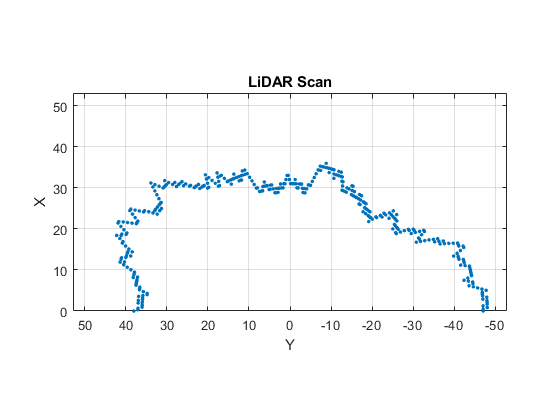

plot(scan)